# Visualisierung von Funktionen und Messwerten

In der Schule haben wir gelernt, einfache Funktionen wie beispielsweise eine Parabel- oder eine Sinusfunktion als Schaubild zu zeichnen. Wenn man jedoch nicht weiß, wie prinzipiell der Graph einer bestimmten Funktion aussieht, legt man eine Wertetabelle an. In MATLAB gehen wir analog dazu vor und starten ebenfalls mit einer Wertetabelle. Danach entscheiden wir uns für einen von drei verschiedenen Diagrammtypen, um diese Wertetabelle zu visualisieren. Der Diagrammtyp richtet sich nach der Quelle der Daten. In diesem MATLAB Live Skript betrachten wir die folgenden Diagrammtypen:

- Liniendiagramm (kontinuierliche Daten),

- Balkendiagramm/Säulendiagramm (diskrete Daten) und

- Streudiagramm (Messwerte).

## Liniendiagramm

Eine der häufigsten Darstellungen von mathematischen Funktionen ist das Liniendiagramm. Zu jedem x-Wert wird der entsprechende y-Wert einer Funktion als Punkt in ein Koordinatensystem mit x- und y-Achse eingetragen und die Punkte werden mit einer geraden Linie verbunden.

Erzeugen wir uns eine Liste mit x-Werten und dazugehörigen y-Werten als Listen.

x = [-2, -1, 0, 1, 2];
y = [4, 1, 0, 1, 4];

Danach kommt die Funktion zum Zeichen der Werte `plot(x,y):`

plot(x,y);

Sieht ziemlich krakelig aus. Eigentlich sollte dies eine Parabel werden im Intervall $\left\lbrack -2,2\right\rbrack$ werden. Mit nur 5 Punkten und der Tatsache, dass diese 5 Punkte mit geraden Linien verbunden werden, sieht es etwas unschön aus. Besser wird es mit mehr Punkten, aber die wollen wir jetzt nicht von Hand erzeugen. Dazu nutzen wir eine der MATLAB-Methoden zur Erzeugung von Vektoren, nämlich `linspace() `und erzeugen neun Punkte zwischen -2 und 2.

x = linspace(-2, 2, 9);
disp(x);

Der resultierende Datentyp von `linspace` ist ein eindimensionales Array, wovon wir uns mit dem Befehl `whos` überzeugen könnten. Wenn wir jetzt zu jedem Element im Array das Quadrat des Elementes bilden sollen, könnten wir eine For-Schleife programmieren, die durch das eindimensionale Array geht und jedes Element quadriert. Glücklicherweise stellt MATLAB für Zahlen-Arrays, also Vektoren oder Matrizen, zusätzliche Funktionen zur Verfügung, die aus der Mathematik stammen. Wenn jedes einzelne Element eines Vektors oder einer Matrix quadriert werden soll,  müssen wir den **Punktoperator** vor der mathematischen Operation benutzen. 

y = x.^2;
disp(y);

Damit können wir nun wiederum ein Liniendiagramm visualisieren:

plot(x,y);

Schon besser, aber noch ein paar mehr Punkte wären noch schöner, probieren wir es mit 100 Punkten:

x = linspace(2, -2, 100);
y = x.^2 +7 ;

plot(x,y);

#### Mini-Übung 1

Bitte plotten Sie folgende Funktionen als Liniendiagramm: 

- $f(x) = 7x + 2$,

- Sinus, 

- Kosinus,

- Exponentialfunktion und 

- Wurzelfunktion.

Verändern Sie auch das Definitionsgebiet der Funktionen, also das Intervall für $x$.

% Hier Ihr Code


**Ein Diagramm muss immer beschriftet sein!**

Mit den Funktionen `xlabel() `und  `ylabel()` beschriften wir die x- und y-Achse.

x = linspace(-10,10,200);
y = sin(x);

plot(x,y);
xlabel('Zeit in Sekunden');
ylabel('Stromstärke in Ampere');

Fehlt noch ein **Titel** für unsere Grafik, das erledigt die Funktion `title(). `Mit dem Befehl` grid on `lassen Sie MATLAB zusätzliche Gitterlinien einzeichnen:

x = linspace(-10,10,200);
y = sin(x);

plot(x,y);
title('Wechselstrom');
xlabel('Zeit in Sekunden');
ylabel('Stromstärke in Ampere');
grid on;

Zuletzt soll unser Plot mit `saveas() `gespeichert werden. Es stehen mehrere Grafikformate zur Verfügung. Mehr Details finden Sie auf der Internetseite

[https://de.mathworks.com/help/matlab/ref/saveas.html](https://de.mathworks.com/help/matlab/ref/saveas.html)

Ein typisches Ausgabeformat ist eine Rastergrafik wie z.B. png. Das erreichen Sie durch den folgenden Funktionsaufruf. Bitte beachten Sie, dass die ID des Grafikobjektes als erstes Argument der `saveas()`-Funktion übergeben müssen. Wenn Sie keine ID gesetzt haben, benutzen Sie einfach `gcf`, (= get current figure), eine Abkürzung für den zuletzt gezeichneten Plot.

x = linspace(-10,10,200);
y = sin(x);

plot(x,y)
xlabel('Zeit in Sekunden')
ylabel('Stromstärke in Ampere')
title('Wechselstrom')
saveas(gcf, 'liniendiagramm_stromstaerke.jpg')

Möchte man zwei oder gar mehrere Funktionen oder Messdaten in einer Grafik darstellen, verwendet man den plot-Befehl mehrfach, setzt aber nach dem ersten plot-Befehl den Befehl `hold on; also`:

x  = linspace(-2*pi,2*pi, 200);
y1 = sin(x);
y2 = cos(x);

plot(x,y1);
hold on;
plot(x,y2);

Ist einmal der Befehl `hold on` verwendet worden, werden alle neuen Diagramme in dieses Fenster eingezeichnet. Daher verwenden wir ab sofort stets den Befehl `figure()` zu Beginn eines neuen Diagramms, um ein leeres Diagramm mit Standardeinstellungen zu starten. Möchten Sie den `hold on` Status ausschalten, können Sie explizit den Befehl `hold off` benutzten.

Sind mehrere Diagramme in einer Grafik zu sehen, dann sollten die Kurven auch beschriftet werden. Dazu verwendet man die Funktion `legend(name1, name2, ...). `

% Erzeugung x-Werte: 
% es muss nicht das gleiche Intervall betrachtet werden
x1  = linspace(-2*pi,2*pi, 200);
x2  = linspace(0, 2*pi, 50); 

% Erzeugung y-Werte
y1 = sin(x1);
y2 = 0.1 * x2;

% Liniendiagramm
figure();
plot(x1,y1);
hold on;
plot(x2,y2);
xlabel('x-Achse');
ylabel('y-Achse');
title('Zwei Funktionen');
legend('Sinus', 'Gerade');


#### Mini-Übung 2

Stellen Sie die Funktionen

- 
$$f1(x) = \sin(x)$$


- 
$$f2(x) = \sin(2x)$$


- 
$$f3(x) = \sin(3x)$$


als Liniendiagramm im Intervall $[-2\pi,2\pi]$ dar und beschriften Sie die Kurven mit einer geeigneten Legende.

% Hier Ihr Code


## Balkendiagramm

Balkendiagramme oder Säulendiagramme werden zur Visualisierung von quantitativen Daten verwendet. Damit ist gemeint, dass auf der x-Achse Kategorien oder Klassen eingetragen werden, zwischen denen auch kein Mittelwert gebildet werden kann. Angenommen, wir haben folgende Daten über die beliebtesten YouTube-Streams (hier bis Mai 2021 ausgewertet) gesammelt:

`YouTuber    Song        Anzahl der Views (in Milliarden)`

`---------------------------------------------------------------------------------------`

`Pinkfong Kids' Songs & Stories   | Baby Shark Dance                          | 8.58`

`Luis Fonsi ft. Daddy Yankee      | Despacito                                 | 7.35`

`LooLoo Kids                      | Johny Johny Yes Papa                      | 5.31`

`Ed Sheeran                       | Shape of You                              | 5.31`

`Wiz Khalifa ft. Charlie Puth     | See You Again                             | 5.1`

`Get Movies                       | Masha and the Bear: Recipe for Disaster   | 4.44`

`Mark Ronson ft. Bruno Mars       | Uptown Funk                               | 4.18`

`Psy                              | Gangnam Style                             | 4.06`

`Miroshka TV                      | Learning Colors - Colorful Eggs on a Farm | 4.05`

`Cocomelon                        | Bath Song                                 | 4.03`

Dann würden wir diese Daten mit einem Balkendiagramm visualisieren, weil auf der x-Achse die Namen von YouTubern stehen, also Klassen oder Kategorien und keine kontinuerlichen x-Daten.

Mit der Funktion `bar()` kann nun ein Balkendiagramm erstellt werden. 

% Erzeugung Wertetabelle
anzahl_views = [8.58, 7.53, 5.31, 5.31, 5.1, 4.44, 4.18, 4.06, 4.05, 4.03];

% Visualisierung
figure();
bar(anzahl_views);

Weitere Details zu der `bar()`-Funktion finden Sie in der MATLAB-Dokumentation:

[https://de.mathworks.com/help/matlab/ref/bar.html](https://de.mathworks.com/help/matlab/ref/bar.html)

Schade, dass wir nur die Nummer des YouTubers ablesen können. Wenn wir anstatt der Nummern die ursprünglichen Kategorien verwenden wollen, müssen wir ein Datenobjekt mit den Kategorien erzeugen. Dazu benutzten wir die Funktion `categorical( {kategorie1, kategorie2, ..., kategorieN} ) `

% Erzeugung Wertetabelle
youtuber = categorical({'Pinkfong', 'Lius Fonsi', 'LooLoo Kids', 'Ed Sheeran',...
    'Wiz Khalifa', 'Get Movies', 'Mark Ronson', 'Psy', 'Miroshka TV', 'Cocomelon'});
anzahl_views = [8.58, 7.53, 5.31, 5.31, 5.1, 4.44, 4.18, 4.06, 4.05, 4.03];

% Visualisierung
figure();
bar(youtuber, anzahl_views);

Wie Sie sehen, hat sich die Reihenfolge der Kategorien und damit der Balken geändert. In der ersten Visualisierung waren die Kategorien implizit mit 1, 2, 3, ... durchnummeriert. Bei der zweiten Visualisierung, in der wir die Kategoriennamen verwendet haben, wurden die Kategorien alphabetisch sortiert. Dadurch hat sich die Reihenfolge geändert. Dies können wir verhindern, indem wir die ursprüngliche Reihenfolge wieder mit der `reordercats()`-Funktion erzwingen:

% Erzeugung Wertetabelle
anzahl_views = [8.58, 7.53, 5.31, 5.31, 5.1, 4.44, 4.18, 4.06, 4.05, 4.03];
youtuber = reordercats(categorical({'Pinkfong', 'Lius Fonsi', 'LooLoo Kids', 'Ed Sheeran',...
    'Wiz Khalifa', 'Get Movies', 'Mark Ronson', 'Psy', 'Miroshka TV', 'Cocomelon'}) , {'Ed Sheeran', 'Pinkfong', 'Lius Fonsi', 'LooLoo Kids',...
    'Wiz Khalifa', 'Get Movies', 'Mark Ronson', 'Psy', 'Miroshka TV', 'Cocomelon'});

% Visualisierung
figure();
bar(youtuber, anzahl_views);

Natürlich funktionieren auch hier die Funktionen `xlabel()`, `ylabel()` und `title()`:

xlabel('YouTuber');
ylabel('Anzahl Views in Mrd.');
title('YouTube-Streams 2021');

#### Mini-Übung 3

Visualisieren Sie die Anzahl der Sitze, die die einzelnen Parteien bei der Bundestagswahl 2021 gewonnen haben in einem Balkendiagramm (Quelle: [https://www.bundeswahlleiter.de/bundestagswahlen/2021/ergebnisse/bund-99.html](https://www.bundeswahlleiter.de/bundestagswahlen/2021/ergebnisse/bund-99.html)):

CDU: 152

SPD: 206

AfD: 83

FDP: 92

DIE LINKE: 39

GRÜNE: 118

CSU: 45

Den SSW mit einem Sitz lassen Sie bitte weg. Ordnen Sie die Balken nach der aktuellen Sitzordnung im Bundestag, siehe ggf. [https://de.wikipedia.org/wiki/Sitzzuteilungsverfahren_nach_der_Wahl_zum_Deutschen_Bundestag](https://de.wikipedia.org/wiki/Sitzzuteilungsverfahren_nach_der_Wahl_zum_Deutschen_Bundestag) . Ergänzen Sie passende Beschriftungen.

% Hier Ihr Code


#### Mini-Übung 4

Wie viele Semesterwochenstunden an Veranstaltungen haben Sie laut Stundenplan in diesem Semester. Visualisieren Sie die Anzahl der Stunden für jeden Wochentag in einem Balkendiagramm mit passenden Beschriftungen.

% Hier Ihr Code


## Streudiagramm

Aber welchen Diagrammtyp nehmen wir nun zum Zeichen der Messwerte? Ein Liniendiagramm scheidet aus, weil Messwerte nicht kontinuierlich gemessen werden. Ein Balkendiagramm passt auch nicht, weil normalerweise keine Kategorien vorliegen. Auerrdem kann es bei Messungen vorkommen, dass für einen x-Wert mehrere y-Werte vorkommen, weil zum Beispiel die Messung mehrfach wiederholt wurde. Daher verwenden wir für Messwerte einen neuen Diagrammtyp, das sogenannte **Streudiagramm** bzw. auf Englisch **Scatterplot**. Die entsprechende MATLAB-Funktion heißt `scatter()`. Mehr Details finden Sie hier:

[https://de.mathworks.com/help/matlab/ref/scatter.html](https://de.mathworks.com/help/matlab/ref/scatter.html)

Alle anderen Befehle können wie gewohnt ebenfalls benutzt werden , also z.B.` title() `für den Titel. 

Als Beispiel für eine Messung nehmen wir den weltweiten CO2-Ausstoß in Mio. Tonnen (Quelle: [https://de.statista.com/statistik/daten/studie/37187/umfrage/der-weltweite-co2-ausstoss-seit-1751/](https://de.statista.com/statistik/daten/studie/37187/umfrage/der-weltweite-co2-ausstoss-seit-1751/) )

% Erzeugung Wertetabelle
x = [1960, 1965, 1970, 1975, 1980, 1985, 1990, 1995, 2000, 2005, 2010, 2011, 2012, 2013,...
     2014, 2015, 2016, 2017, 2018, 2019, 2020];
y = 1.0e+04 * [0.9387, 1.1317, 1.4898, 1.7046, 1.9493, 2.0317, 2.2750, 2.3454, 2.5234, 2.9603,...
    3.3343, 3.4468, 3.4974, 3.5283, 3.5534, 3.5496, 3.5452, 3.5926, 3.6646, 3.6702, 3.4807];

% Visualisierung
figure()
scatter(x,y);
xlabel('Jahr');
ylabel('CO2');
title('Weltweiter Ausstoß bis 2020 in Mio. Tonnen');

Gerade bei Messwerten ist es oft sinnvoll, zwischen Versuchsreihen zu unterscheiden. Dementsprechend bietet das Streudiagramm zahlreiche Einstellmöglichkeiten. Wir betrachten im Folgenden drei verschiedene Optionen, um Messwerte in Streudiagrammen zu visualisieren:

- Größe des Markers,

- Farbe des Markers und

- Markersymbol.

Mit Marker ist dabei das Zeichen gemeint, mit dem die Messwerte in das Diagramm eingetagen werden.

Im folgenden Beispiel erzeugen wir sechs Lottozahlen und tragen sie in ein Streudiagramm. Diesmal übergeben wir der `scatter()`-Funktion die Größe als drittes Argument:

`scatter(x,y, size)`.

Variieren Sie die Größe händisch mit Werten zwischen 10 und 500:

% Erzeugung Wertetabelle
x = [1, 2, 3, 4, 5, 6];
y = randi([1, 49], 1, 6);

% Visualisierung
figure();
scatter(x, y, 10);
title('Lottozahlen');
xlabel('Nummer');
ylabel('gezogene Lottozahl');
grid on;

Dabei muss der dritte Parameter keine feste Zahl sein, sondern kann ebenfalls ein Vektor sein.

#### **Mini-Übung 5**

Erzeugen Sie drei Vektoren $x$, $y$ und $s$. $x$ soll die Zahlen von 1 bis 10 enthalten und $y$ soll ganzzahlige Zufallszahlen zwischen -3 und 3 enthalten. Die einzelnen Elemente $s_i$ in $s$ sollen nach der Formel $s_i = 100 + 100 \cdot y_i^2$ berechnet werden. Visualisieren Sie diese Daten als Streudiagramm mit $s$ als variable Größe.

% Hier Ihr Code


Die Farbe des Markers wird als viertes Argument gesetzt. 

`scatter(x, y, size, color).`

Dabei müssen die Farben in MATLAB-Syntax angegeben werden. Die Standardfarben können über ihre englischen Bezeichnungen verwendet werden:

`'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white' `

Wenn jetzt die Marker rot gefärbt werden sollen, setzen wir als viertes Argument `'red'`. Macnhmal möchten wir die Größe bei der Voreinstellung belassen, aber trotzdem die Farbe ändern. In diesem Fall können wir nicht einfach das dritte Argument weglassen, sondern kennzeichnen es als Standard, indem wir leere eckige Klammern als drittes Argument für die Größe verwenden.

% Erzeugung Wertetabelle
x = [1, 2, 3, 4, 5, 6];
y = randi([1, 49], 1, 6);

% Visualisierung
figure();
scatter(x, y, [], 'red');
title('Lottozahlen');
grid on;

#### Mini-Übung 6

Erzeugen Sie einen Vektor mit ganzen Zahlen von 1 bis 25 (Nummern der Schüler:innen einer Klasse). Erzeugen Sie dann einen Vektor mit 25 Elementen (also Size 1x25), der zufällige Schulnoten von 1 bis 6 beinhaltet. Lassen Sie dann (Tipp: beispielsweise in einer For-Schleife) die einzelnen Noten nach dem folgenden Muster visualisieren:  Wenn die Schulnote des i-ten Schülers eine 1 oder 2 ist, soll der Marker `'green' `angezeigt werden`, `bei 3 oder 4 `'yellow'`  und ansonsten `'red'`. Visualisieren Sie die Daten als Streudiagramm. 

% Hier Ihr Code



Zuletzt variieren wir noch die Marker selbst. Das folgende Bild ist ein Ausschnitt aus der MATLAB-Dokumentation und zeigt das Aussehen der verschiedenen Markersymbole und ihre Bezeichnung.

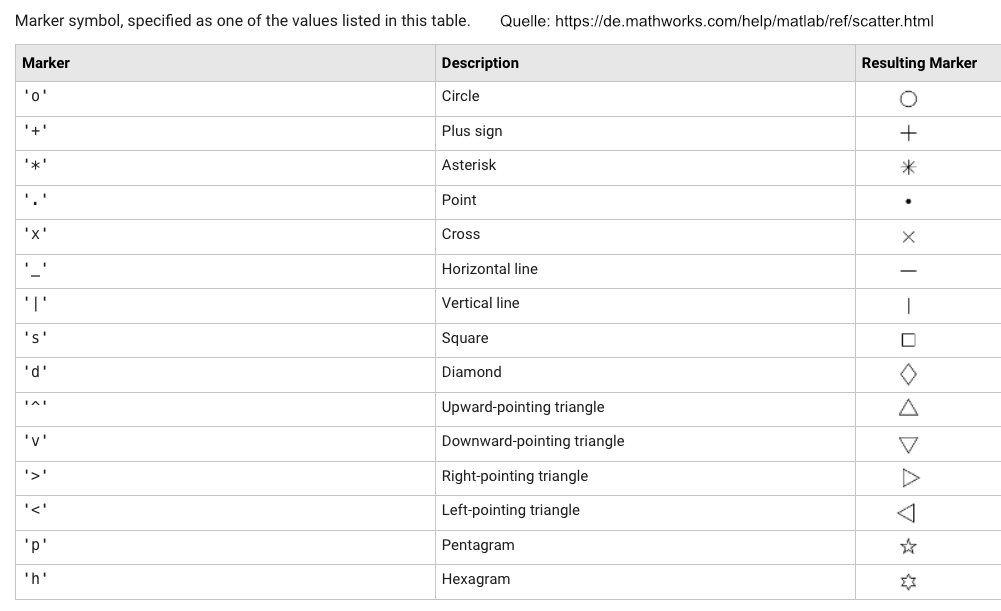

Der folgende Code zeigt Ihnen Zufallszahlen mit verschiedenen Markersymbolen:

% Erzeugung Wertetabelle
x = linspace(1, 10, 10);
y = randi([-3, 3], 1, 10);

for marker = ['*', '+', 'd', 'p']
   fprintf('Jetzt kommt Markersymbol: %s', marker);

   figure();
   scatter(x, y, marker);
end


## Zusammenfassung

Die Visualisierung der Daten in Form von Balken- oder Streudiagrammen ist normalerweise der erste Schritt bei einer Datenanalyse. Durch die Visualisierung gewinnen wir einen ersten Eindruck darüber, ob statistische Ausreißer vorliegen oder in den Daten ein Muster erkennbar ist.  Mit der Erkennung von Mustern und Gesetzmäßigkeiten in Form der linearen Regressin werden wir uns im nächsten Skript beschäftige

## Lösungen zu den Mini-Übungen

**Lösung zu Mini-Übung 1**

Bitte plotten Sie folgende Funktionen als Liniendiagramm: 

- $f(x) = 7x + 2$,

- Sinus, 

- Kosinus,

- Exponentialfunktion und 

- Wurzelfunktion.

Verändern Sie auch das Definitionsgebiet der Funktionen, also das Intervall für $x$.

% Erzeugung x-Werte
x = linspace(-3,3, 100);

% y-Werte der fünf Funktionen
y1 = 7 * x + 2;
y2 = sin(x);
y3 = cos(x);
y4 = exp(x);
y5 = sqrt(x);

% Liniendiagramm: ersetze die y-Werte jeweils durch y1, y2, ..., y5
plot(x,y1);

**Lösung zu Mini-Übung 2**

Stellen Sie die Funktionen

- 
$$f1(x) = \sin(x)$$


- 
$$f2(x) = \sin(2x)$$


- 
$$f3(x) = \sin(3x)$$


als Liniendiagramm im Intervall $[-2\pi,2\pi]$ dar und beschriften Sie die Kurven mit einer geeigneten Legende.

% Erzeugung Werte-Tabelle
x = linspace(-2*pi, 2*pi);
y1 = sin(x);
y2 = sin(2 .* x);
y3 = sin(3 .* x);

% Visualisierung
figure();
plot(x, y1);
hold on;
plot(x, y2);
plot(x, y3);
legend('sin(x)', 'sin(2x)', 'sin(3x)');

**Lösung zu Mini-Übung 3**

Visualisieren Sie die Anzahl der Sitze, die die einzelnen Parteien bei der Bundestagswahl 2021 gewonnen haben in einem Balkendiagramm (Quelle: [https://www.bundeswahlleiter.de/bundestagswahlen/2021/ergebnisse/bund-99.html](https://www.bundeswahlleiter.de/bundestagswahlen/2021/ergebnisse/bund-99.html)):

CDU: 152

SPD: 206

AfD: 83

FDP: 92

DIE LINKE: 39

GRÜNE: 118

CSU: 45

Den SSW mit einem Sitz lassen Sie bitte weg. Ordnen Sie die Balken nach der aktuellen Sitzordnung im Bundestag, siehe ggf. [https://de.wikipedia.org/wiki/Sitzzuteilungsverfahren_nach_der_Wahl_zum_Deutschen_Bundestag](https://de.wikipedia.org/wiki/Sitzzuteilungsverfahren_nach_der_Wahl_zum_Deutschen_Bundestag) . Ergänzen Sie passende Beschriftungen.

% Erzeugung Wertetabelle
parteien = categorical({'CDU', 'SPD', 'AfD', 'FDP', 'DIE LINKE', 'GRÜNE', 'CSU' });
parteien_geordnet = reordercats(parteien, {'DIE LINKE', 'GRÜNE', 'SPD', 'FDP', 'CDU', 'CSU', 'AfD'} );

anzahl_sitze = [152, 206, 83, 92, 39, 118, 45];

% Visualisierung
figure();
bar(parteien_geordnet, anzahl_sitze);
xlabel('Partei');
ylabel('Anzahl Sitze');
title('Bundestagswahl 2021');

**Lösung zu Mini-Übung 4**

Wie viele Semesterwochenstunden an Veranstaltungen haben Sie laut Stundenplan in diesem Semester. Visualisieren Sie die Anzahl der Stunden für jeden Wochentag in einem Balkendiagramm mit passenden Beschriftungen.

% Erzeugung Wertetabelle
sws = [8,6,4,0,8];
woche = categorical({'Mo', 'Di', 'Mi', 'Do', 'Fr'});
woche_geordnet = reordercats(woche, {'Mo', 'Di', 'Mi', 'Do', 'Fr'});

% Visualisierung
figure();
bar(woche_geordnet, sws);
ylabel('Anzahl SWS');
title('Mein Stundenplan');

**Lösung zu Mini-Übung 5**

Erzeugen Sie drei Vektoren $x$, $y$ und $s$. $x$ soll die Zahlen von 1 bis 10 enthalten und $y$ soll ganzzahlige Zufallszahlen zwischen -3 und 3 enthalten. Die einzelnen Elemente $s_i$ in $s$ sollen nach der Formel $s_i = 100 + 100 \cdot y_i^2$ berechnet werden. Visualisieren Sie diese Daten als Streudiagramm mit $s$ als variable Größe.

% Erzeugung der Wertetabelle
x = linspace(1, 10, 10);
y = randi([-3, 3], 1, 10);
s = 100 + 100 * y .^2;         % Punktoperstor wichtig, weil elemetweise quadriert wird

% Visualisierung
figure();
scatter(x, y, s);

**Lösung zu Mini-Übung 6**

Erzeugen Sie einen Vektor mit ganzen Zahlen von 1 bis 25 (Nummern der Schüler:innen einer Klasse). Erzeugen Sie dann einen Vektor mit 25 Elementen (also Size 1x25), der zufällige Schulnoten von 1 bis 6 beinhaltet. Lassen Sie dann (Tipp: beispielsweise in einer For-Schleife) die einzelnen Noten nach dem folgenden Muster visualisieren:  Wenn die Schulnote des i-ten Schülers eine 1 oder 2 ist, soll der Marker `'green' `angezeigt werden`, `bei 3 oder 4 `'yellow'`  und ansonsten `'red'`. Visualisieren Sie die Daten als Streudiagramm. 

% Erzeugung Wertetabelle
x = linspace(1, 25, 25);
y = randi([1, 6], 1, 25);

% Visualisierung
figure();
hold on;
for i = 1:25
    if y(i) == 1 || y(i) == 2
        scatter(x(i), y(i), 'green');
    elseif y(i) == 3 || y(i) == 4
        scatter(x(i), y(i), 'yellow');
    else
        scatter(x(i), y(i), 'red');
    end
end
grid on;
xlabel('Nr. Schüler:in');
ylabel('Note');
title('Notenspiegel');


% Visualisierung
figure();
scatter(x, y, [], c);